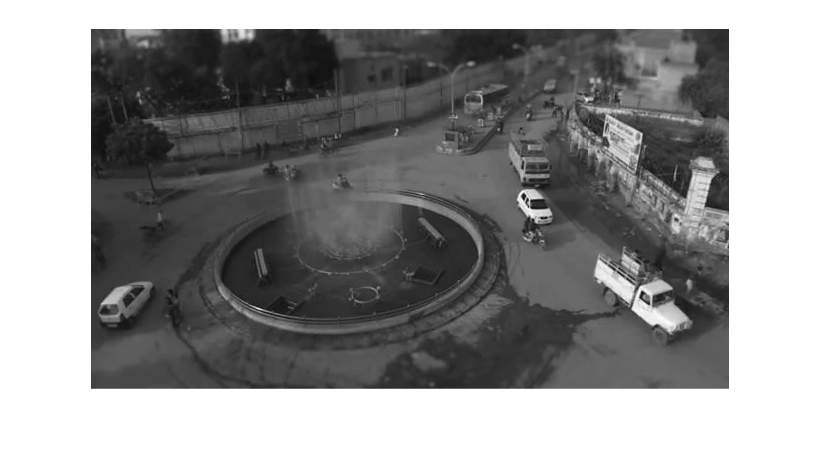

% Step 1: Read the video and convert it to grayscale and add noise
video_path = 'Indiantraffic.avi';

video_obj = VideoReader(video_path);
frame_rate = video_obj.FrameRate;
num_frames = video_obj.NumFrames;

error = 4.6243e-06

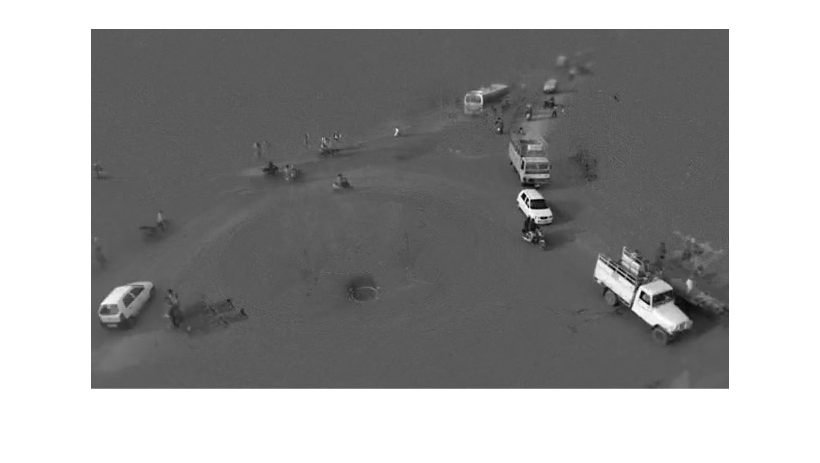

video_height = video_obj.Height;
video_width = video_obj.Width;
%just 10 seconds
noisy_video_gray = zeros(frame_rate*10, video_height*video_width);
for i = 1:(frame_rate*10)
    frame_rgb = read(video_obj, i);
    frame_gray = rgb2gray(frame_rgb);
%     frame = imnoise(frame_gray, 'salt & pepper');
    noisy_video_gray(i,:) = reshape(frame,[],1);
end
imshow(frame)


[L,S,error] = ROBPCA(videoMatrix, 1e-4, 1e-3, 0.5e-5);

error

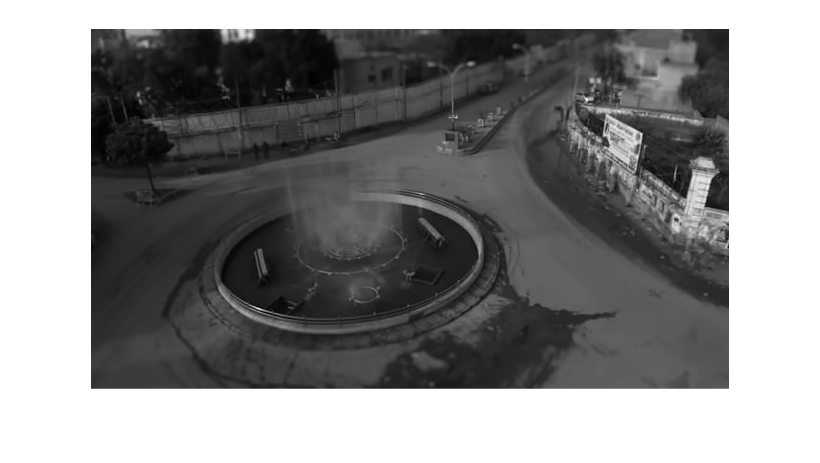

%save video of the foreground
video = VideoWriter('foreground.avi');
video.FrameRate = frate;
open(video);
for i = 1:size(videoMatrix)
    frame = reshape(S(i,:), height, []);
    frame = mat2gray(frame);
    writeVideo(video, frame);
end

close(video);
imshow(frame)
%save the video of background
video = VideoWriter('background.avi');
video.FrameRate = frate;
open(video);
for i = 1:size(videoMatrix)
    frame = reshape(L(i,:), height, []);
    frame = mat2gray(frame);
    writeVideo(video, frame);
end
close(video);
imshow(frame)

function [L,S,err] = ROBPCA(M, lambda, mu, tol)
%initialize S L and Y
    S = zeros(size(M));
    L = zeros(size(M));
    Y = zeros(size(M));
    normM = norm(M, 'fro');
    for iter = (1:1000)
        [U_1, S_1, V_1] = svd(M-S+(1/mu)*Y, 'econ');
        L = U_1*(sign(S_1) .* max(abs(S_1)-(1/mu), 0))*V_1';
        S = sign(M-L +(1/mu)*Y) .* max(abs(M-L +(1/mu)*Y)-(lambda/mu), 0);
        Z = M-L-S;
        Y = Y+mu*Z;     
        err = norm(Z, 'fro') / normM;
        if (err < tol)
            break;
        end
    end
end